# Aula 5 - Lugar das Raízes


$$G(s)=\frac{K}{s(s+2)(s^2+4s+5)}$$


a)Esboce o Lugar das Raízes utilizando todas as regras

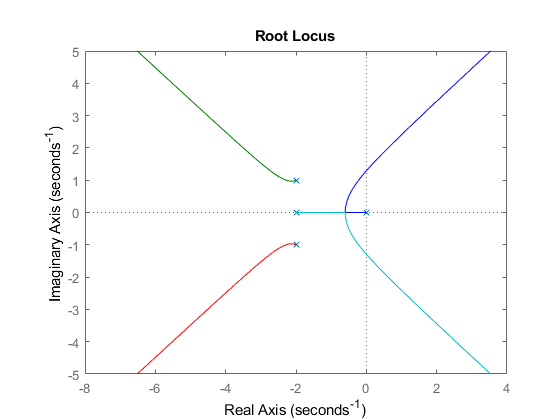

clear
den=conv(conv([1,0],[1,2]),[1,4,5]);
G=tf(1,den);
rlocus(G)

b) Mostre que as raízes dominantes, quando K=6,5, são − 0, 35±0, 8j

FT=feedback(6.5*G,1);
damp(FT)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -3.49e-01 + 8.00e-01i     4.00e-01       8.73e-01         2.86e+00    
 -3.49e-01 - 8.00e-01i     4.00e-01       8.73e-01         2.86e+00    
 -2.65e+00 + 1.23e+00i     9.07e-01       2.92e+00         3.77e-01    
 -2.65e+00 - 1.23e+00i     9.07e-01       2.92e+00         3.77e-01    


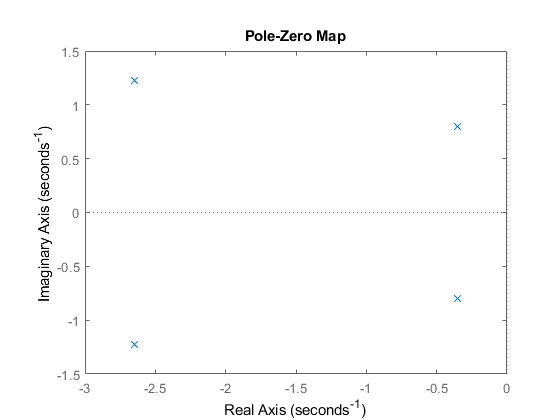

pzmap(FT)

c)Obtenha a resposta a degrau aproximada neste caso

step(FT)
stepinfo(FT)

ans = struct with fields:
        RiseTime: 1.8323
    SettlingTime: 10.2697
     SettlingMin: 0.9133
     SettlingMax: 1.2382
       Overshoot: 23.8210
      Undershoot: 0
            Peak: 1.2382
        PeakTime: 4.5866


d) Obtenha K para estabilidade

Executar rlocus(G) e ver o valor de K onde o LR cruza com o eixo y ou fazer manualmente o critério de estabilidade de Routh-Hurwitz na função de transferência abaixo:

syms K s
Gk=1/(s^4+6*s^3+13*s^2+10*s);
FT_k=(K*Gk)/(1+K*Gk);
simplify(FT_k)

$$ans = \frac{K}{s^{4}+6\,s^{3}+13\,s^{2}+10\,s+K}$$

clear K s Gk
close all
hold off
rlocus(G)

s=1.291i;
K=abs(s^4+6*s^3+13*s^2+10*s)

K = 18.8890